# Laboratorio No. 4

# Diana Carolina Cruz Palacios, Daniel Fernando Díaz Coy, Michael Alexander Rodriguez Urbina

Robotica 2021-1 

## 1 Objetivos

1.1 Hacer una introducción al manejo de la herramienta MATLAB® para la simulación de robots. 

1.2 Simular el comportamiento del robot industrial (asignado a su grupo) teniendo en cuenta sus características y haciendo uso de los toolboxes RVCtools de Peter Corke y Robotics System Toolbox (RST) de MATLAB® 

1.3 Construir los modelos cinemáticos directo, inverso y diferencial de un robot Industrial 

1.4 Generar rutas y trayectorias y simular el seguimiento de las trayectorias. Implementar una GUI en MATLAB®para demostrar el funcionamiento de los modelos

## 2. Requisitos

Toolboxes RVCtools de Peter Corke y Robotics System Toolbox instalados.

## 3. Asignacion del Robot

Tabla 1.  Asignacion de Grupos

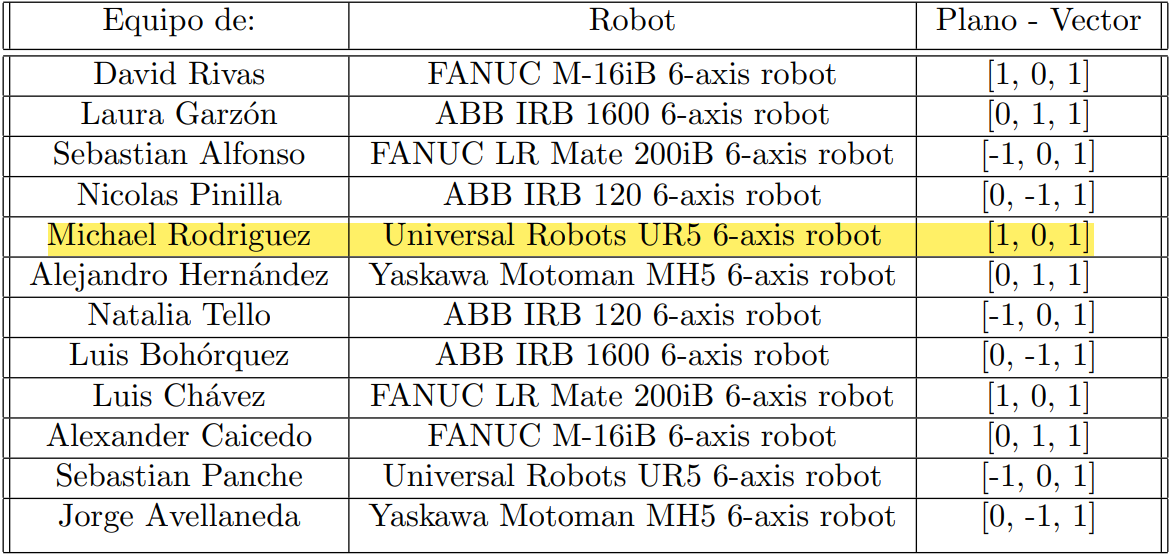 

Nuestro grupo de trabajo tiene asignado el robot ***UR5*** de Universal Robotics

## 4. Localización de ruta

#### 4.1 Plano - Vector, significa que la ruta que el robot va a simular debe estar en un plano normal al vector indicado en la tabla. en nuestro caso usaremos el vector [1,0,1]

#### 4.2 La ruta debe tener una de las dos formas mostradas en la figura. Cada grupo selecciona la que deseen. 

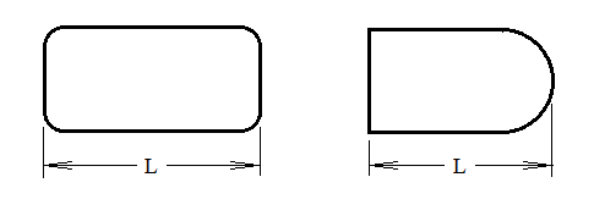

Figura 1. Opciones de selección de ruta

#### 4.3 La dimensión L debe ser aproximadamente 0,4 del alcance horizontal máximo del robot. 

#### 4.4 El grupo decide la posición de la ruta en el espacio cartesiano de manera que quede dentro del espacio diestro del robot. 

#### 4.5 Resultado

Se escogio el tipo de trayectoria de la derecha de la figura 1, la dimension elegida es $L=0.4m$ lo que permite ubicarla en el espacio de trabajo del robot. 

Como comprobacion de los puntos escojidos hacemos una ecuacion general del plano en el espacio teniendo en cuenta el vector normal, este surge de la definicion del plano mediante la operacion $\vec{P}\cdot \vec{N}=0$. El Vector P puede definirse como un vector perteneciente al plano desplazado una posicion $(x_0,y_0,z_0)$, de modo que   $\vec{P}=[(x-x_0),(y-y_0),(z-z_0)]$. Haciendo el producto punto del vector $\vec{P}\cdot \vec{N}=[(x-x_0),(y-y_0),(z-z_0)]\cdot [1,0,1]=0$ entonces $(x-x_0)+(z-z_0)=0\rightarrow x+z=(x_0+z_0)$ y asi obtenemos la ecuacion del plano desplazado en el espacio que contiene nuestra trayectoria.

Con el fin de optimizar el resultado se busco que la division de puntos equidistantes (mencionado en el aparte de Integración) fuera similar tanto en las trayectorias lineales como en la curva, teniendo como resultado que la cantidad de puntos necesarios que cumplen el requisito es $64\cdot n$

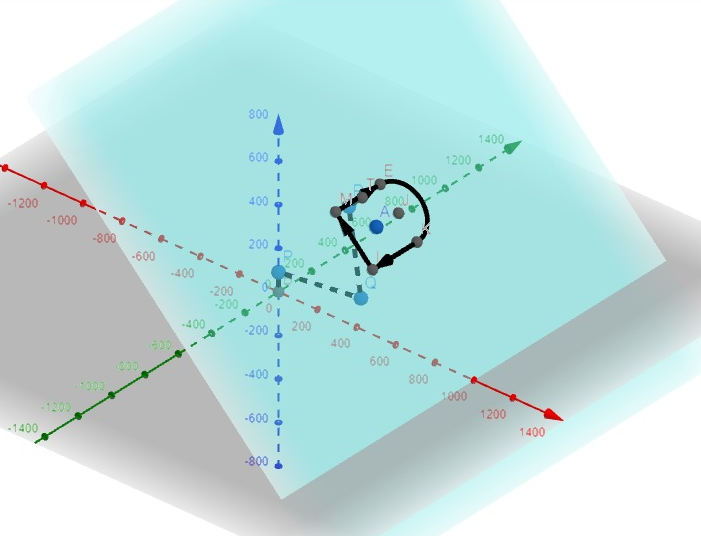 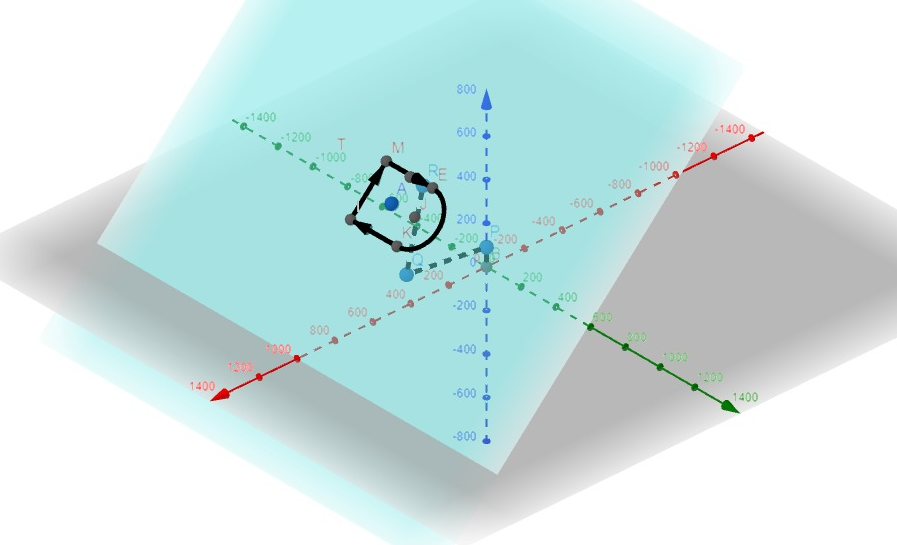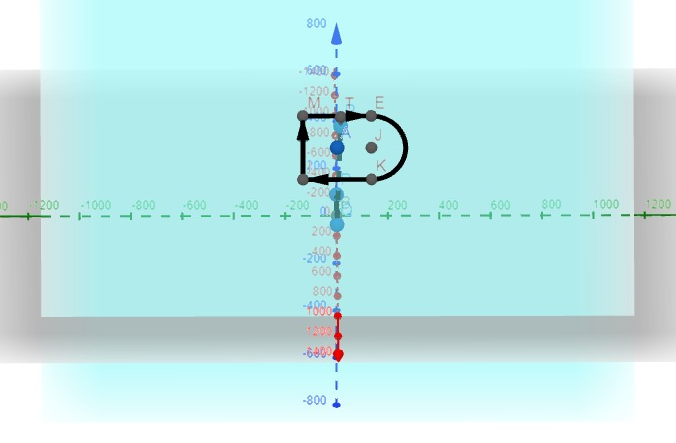

Figura 2.  Ubicación de la ruta elegida

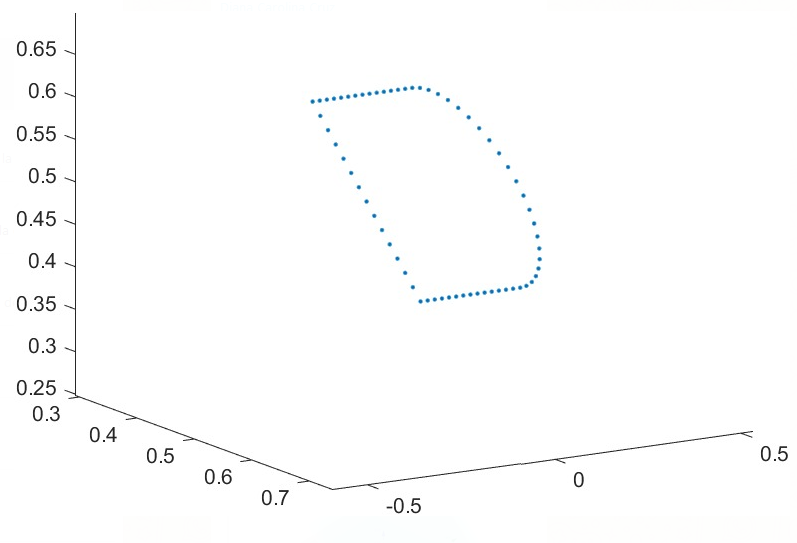

Figura3. Primera ubicación espacial de puntos

% parametro t
t=0.019048;

K = [0.59428, 0.13333, 0.40572];
M = [0.40572, -0.13333, 0.59428];
E = [0.40572, 0.13333, 0.59428];
I = [0.59428, -0.13333, 0.40572];

J = [0.5, 0.13333, 0.5];

%recta entre 2 puntos KI = I-K
punto=[0.59428, 0.13333, 0.40572]';
for i=1:14
    punto (:,i+1)=[K(1),(K(2)-i*t),K(3)];
end

%Recta ENTRE 2 PUNTOS ME IM=M-I
%punto(:,16)= [0.59428, -0.13333, 0.40572]';

for i=1:14
    punto (:,i+15)=[(I(1)-i*t/sqrt(2)),(I(2)),(I(3)+i*t/sqrt(2))];
end

%Recta ENTRE 2 PUNTOS ME ME=E-M
%punto(:,31)= [0.40572, -0.13333, 0.59428]';

for i=1:14
    punto (:,i+29)=[M(1),(M(2)+i*t),M(3)];
end

%Semicirculo centro radio JK, EMPIEZA EN E, TERMINA EN K

j=-90;
for i=1:22
    
    punto (:,i+43)= [J(1)+(J(1)-E(1))*sind(t+j),J(2)+J(2)*cosd(t+j), J(3)+(J(3)-E(3))*sind(t+j)];
    j=j+8.2;
end


p = plot3(punto(1,:),punto(2,:),punto(3,:),'.');

## 5. Características y modelo del robot

#### 5.1 Imagenes del robot.  

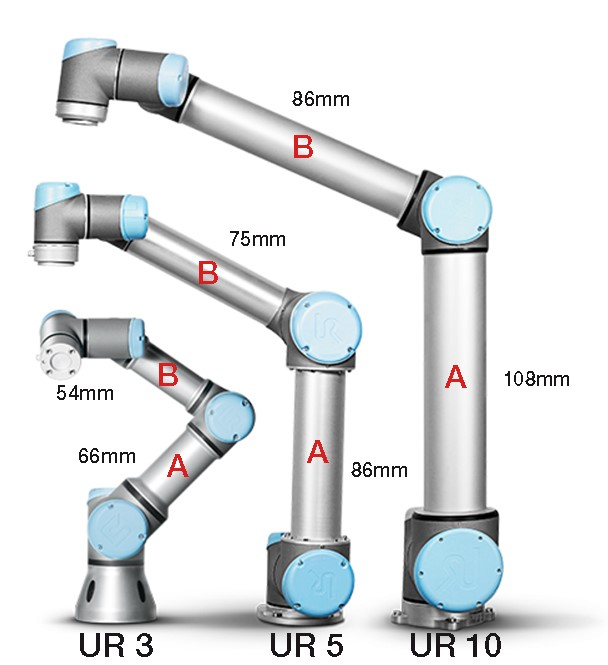  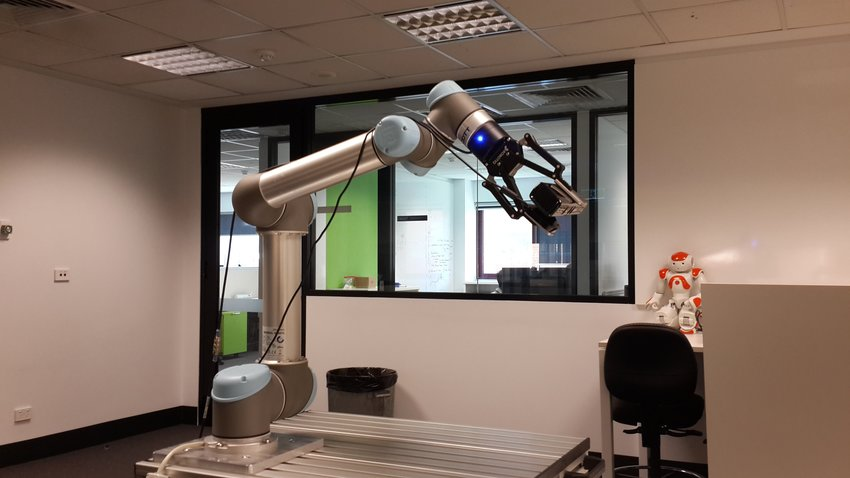

Figura 4. Ilustraciónes del robot

#### 5.2 Capacidad de carga.  

El robot tiene una capacidad de carga de 5kg/11lb 

#### 5.3 Alcance vertical y horizontal.  

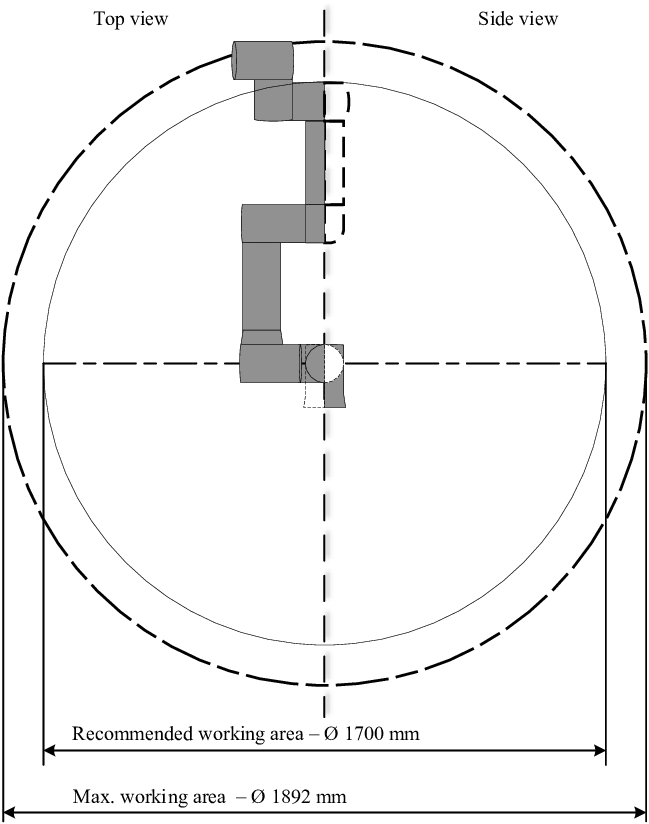 

Figura 5. Extension

Fuente: [https://www.researchgate.net/figure/Collaborative-robot-UR5-working-area-top-side-view_fig1_347021253](https://www.researchgate.net/figure/Collaborative-robot-UR5-working-area-top-side-view_fig1_347021253) 

Al ser un robot sin limitaciones aparentes en la rotacion de sus articulaciones (-360° a 360°) el espacio alcanzable es una esfera

#### 5.4 Repetibilidad.  

Segun la hoja técnica del robot, este tiene una repetibilidad de +/- 0.1 mm 

#### 5.5 Gráfica(s) de espacio alcanzable.  

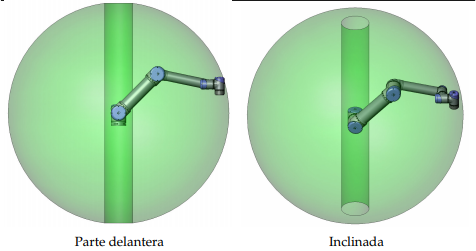 

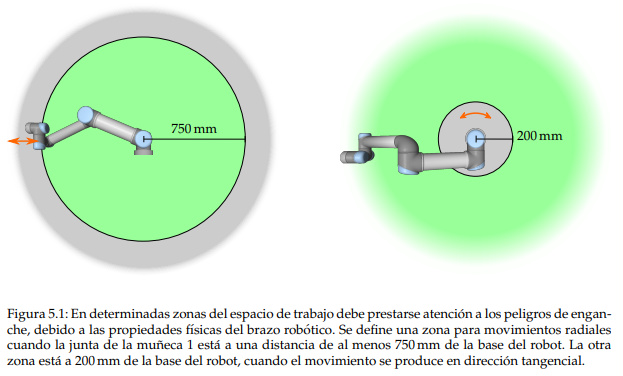 

Figura 6. Espacio Alcanzable del robot UR5

Fuente: [https://www.universal-robots.com/media/1803022/5ework.png?width=704&height=731](https://www.universal-robots.com/media/1803022/5ework.png?width=704&height=731)  

#### 5.6 Tabla de parámetros DH.  

Aunque mas adelante obtenemos esta tabla, se pueden encontrar en varios articulos que muestran la operación de este robot como los autores obtienen la tabla de parametros DH de acuerdo a su posicion de Home, en este caso ellos colocan el robot en posición vertical

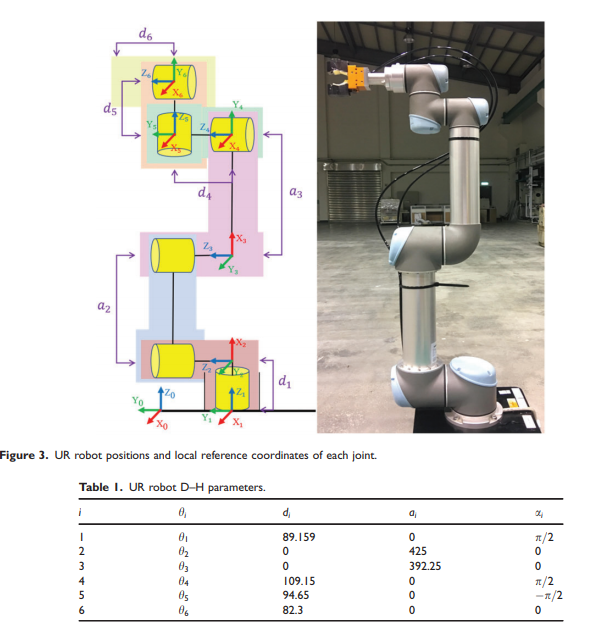 

Figura 7. Tabla de parametros DH obtenida en el articulo "An image vision and automatic calibration system for universal robots"

Fuente: https://journals.sagepub.com/doi/pdf/10.1177/1461348419874925

#### 5.7 ¿Qué software utiliza el fabricante para diseño de celdas o programación?. 

Usa un programa propietario llamado PolyScope, requiere de un controlador propio de la marca alimentado por 24V, la programación se realiza por bloques de código dentro de la interfaz 

El robot se comunica a la interfaz PC por medio del protocolo MODBUS ([Modbus - Wikipedia, la enciclopedia libre](https://es.wikipedia.org/wiki/Modbus))  

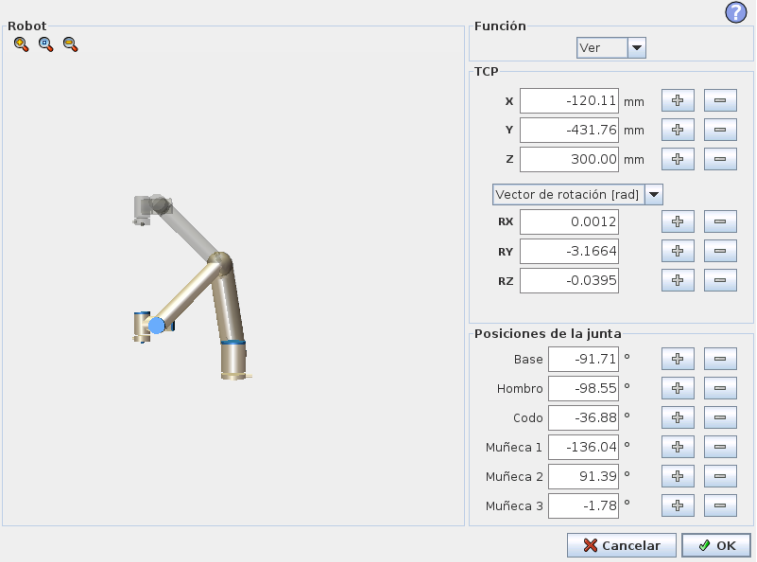 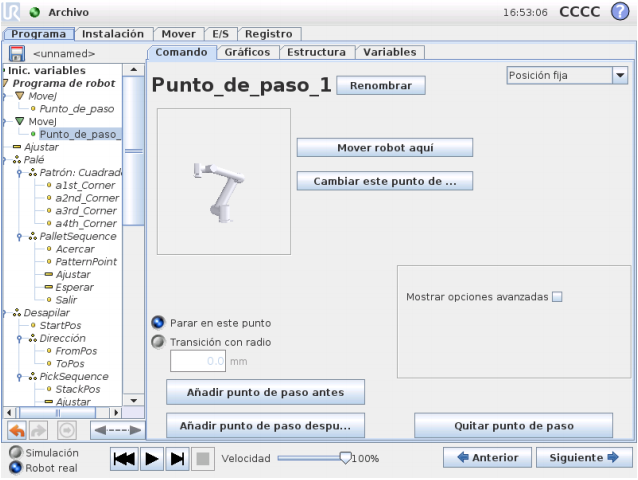

Figura 8. Ejemplos de ventanas de comandos de PolyScope

#### 5.8 Enlaces de Interés

Especificaciones técnicas básicas: [https://www.universal-robots.com/media/50588/ur5_en.pdf](https://www.universal-robots.com/media/50588/ur5_en.pdf)

Manual de usuario: [https://www.cfzcobots.com/wp-content/uploads/2017/03/ur5_user_manual_es_global.pdf](https://www.cfzcobots.com/wp-content/uploads/2017/03/ur5_user_manual_es_global.pdf)

Ejemplo de Código de operacion: [https://www.zacobria.com/universal-robots-zacobria-forum-hints-tips-how-to/script-client-server-example/](https://www.zacobria.com/universal-robots-zacobria-forum-hints-tips-how-to/script-client-server-example/)

## 6. Iniciando el Análisis

Haciendo uso de MATLAB® y los toolboxes ***construya un modelo del robot o utilice uno disponible en los toolboxes y que corresponda al robot asignado.***

Para el inicio del análisis y que el archivo mlx pueda ser ejecutado en cualquier computador , se carga inicialmente el Toolbox de peter corke RVC y se eliminan las variables que esten presentes antes de esta inicialización

addpath 'C:\Program Files\MATLAB\R2020b\toolbox\rvctools'
startup_rvc
clc; 
clear all;
close all;

### 6.1 Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.

#### 6.1.1 Obtención de los parametros DH

Los datos obtenidos de las longitudes de los eslabones y su ubicacion en el espacio debido a que las articulaciones del robot no comparten un plano de trabajo debido a su construccion. Debido a esto se buscaron las dimensiones estandar del robot pero la pagina del fabricante no comparte esta informacion. Por ello en un acto de recursividad se extrajeron las dimensiones del modelo URDF que usa el toolbox de matlab, esto nos permite obtener una excelente precision en la obtencion de los datos.

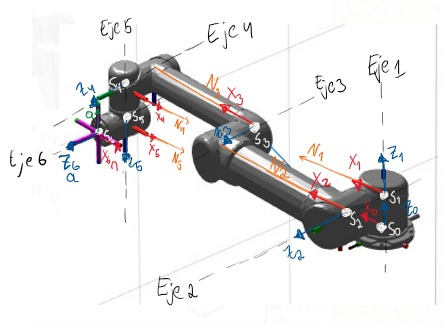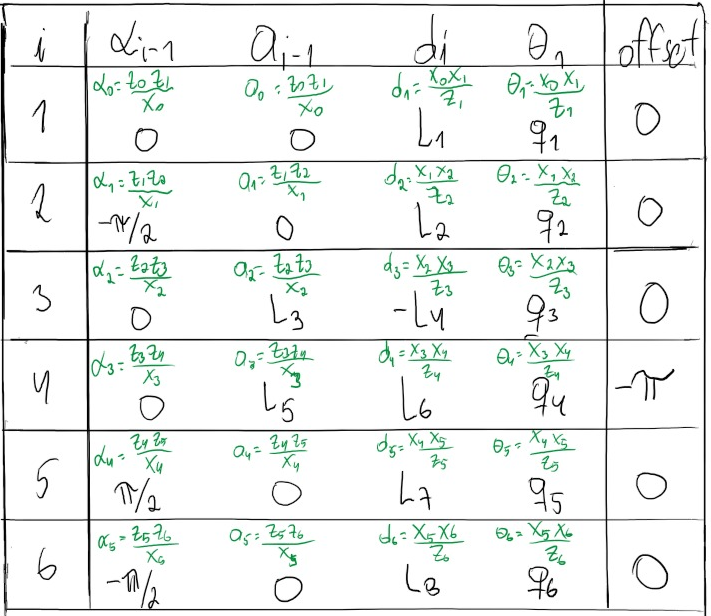

Figura 9. Obtención manual de parametros DHmod del robot UR5

Se establecio que la posición de home usada para nuestro laboratorio sera la misma posición de home del toolbox de Matlab RST para facilitar las comprobaciones.

#### 6.1.2 Construccion del robot serial usando RVC

Con los parametros obtenidos anteriormente se genera el robot

% Li indica las longitudes extraidas del modelo URDF del robot, todas ellas
% son usadas en el análisis
L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.093; L7=  0.09465; L8= 0.0823; 

L9 = 0; %L9 Es la distancia del Tool, pero para comparar resultados facilmente se deja como cero

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')
UR5_RVC.plot([0 0 0 0 0 0],'workspace',[-5 5 -5 5 -1 3],'noa','view',[20 10]);
UR5_RVC.teach;

### 6.2 Considerando el robot asignado, construya el modelo del robot utilizando RST.

Debido a que el toolbox de Matlab posee el robot UR5 en el toolbox como un robot de ejemplo, se utiliza el robot directamente sin necesidad de construirlo

UR5_RST = loadrobot("universalUR5");
show(UR5_RST);

### 6.3 Compare los dos métodos.

El metodo del toolbox RVC depende de la configuracion que el usuario defina en su robot como home, y los parametros deben ingresarse manualmente sin importar el tipo de robot ya que el toolbox no posee robots preestablecidos. Por otro lado el toolbox de Matlab, RST, como posee el robot en sus archivos, y este robot tiene una configuracion de home definida desde el toolbox es mas simple generar el modelo de robot y operar con el. Ademas de esto, el toolbox RST al usar modelos 3D cargados desde una interfaz de ROS es visualmente mas realista que el modelo de alambres que se genera con el toolbox RVC

De manera similar, las funciones y metodos de ambos toolboxes son distintas y se operan de maneras diferentes.

### 6.4 Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.

El fabricante en su manual de usuario y en su manual de servicio tecnico no provee puntos de calibracion. Existe una normativa ISO (ISO 9283) que provee un metodo de calibracion para robots industriales. Fuente: [ISO9283 Performance Testing - RoboDK Documentation](https://robodk.com/doc/en/Robot-Validation-ISO9283.html) 

## 7 Modelo geométrico directo

### 7.1 Halle el modelo geométrico directo de su robot asignado usando MTH. 

% Se borran las variables anteriores y se cierran las instancias de
% funciones creadas
clc; clear all; close all;

% Se crea de manera simbolica las variables qi y Li que indican ángulo de
% articulacion y longitudes respectivamente
syms  q1 q2 q3 q4 q5 q6 L1 L2 L3 L4 L5 L6 L7 L8 L9

% Se definen los eslabones del robot serial
L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',sym(-pi/2),'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',sym(-pi),'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',sym(pi/2),'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',sym(-pi/2),'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

% Se crea el elemento tipo "SerialLink" del toolbox RVC
UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         L1|          0|          0|          0|
|  2|         q2|         L2|          0|      -pi/2|          0|
|  3|         q3|        -L4|         L3|          0|          0|
|  4|         q4|         L6|         L5|          0|        -pi|
|  5|         q5|         L7|          0|       pi/2|          0|
|  6|         q6|         L8|          0|      -pi/2|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

% Se define la MTH de la herramienta 
UR5_RVC.tool = [ 1 0 0 0; 0 1 0 0; 0 0 1 L9; 0 0 0 1]

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         L1|          0|          0|          0|
|  2|         q2|         L2|          0|      -pi/2|          0|
|  3|         q3|        -L4|         L3|          0|          0|
|  4|         q4|         L6|         L5|          0|        -pi|
|  5|         q5|         L7|          0|       pi/2|          0|
|  6|         q6|         L8|          0|      -pi/2|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =   1  0  0  0             
          0         0  1  0  0            0  1  0  0         


%Calculo de T_0_1
T_0_1 = L(1).A(q1) 

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_1_2
T_1_2 = L(2).A(q2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & L_{2}\\ -\sin\left(q_{2}\right) & -\cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_2_3
T_2_3 = L(3).A(q3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & L_{3}\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & -L_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_3_4
T_3_4 = L(4).A(q4)

$$T\_3\_4 = \left(\begin{array}{cccc} -\cos\left(q_{4}\right) & \sin\left(q_{4}\right) & 0 & L_{5}\\ -\sin\left(q_{4}\right) & -\cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & 1 & L_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_4_5
T_4_5 = L(5).A(q5)

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & 0\\ 0 & 0 & -1 & -L_{7}\\ \sin\left(q_{5}\right) & \cos\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_5_6
T_5_6 = L(6).A(q6)

$$T\_5\_6 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 1 & L_{8}\\ -\sin\left(q_{6}\right) & -\cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de MTH general de manera simbólica
T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

### 7.2 Haciendo uso del modelo cinemático directo obtenga los valores de posición y de orientación en coordenadas generalizadas del efector final de su robot asignado para los siguientes valores articulares: 


L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.093; L7=  0.09465; L8= 0.0823; 
L9 = 0; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

 UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

 UR5_RVC.tool = [ 1 0 0 0; 0 1 0 0; 0 0 1 L9; 0 0 0 1]

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

Una vez creado el robot se procede a realizar los calculos de cinematica directa con los valores siguientes:

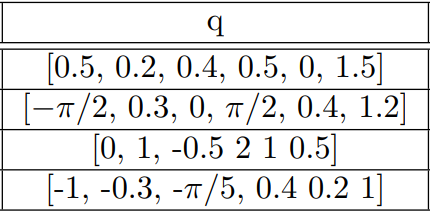

Tabla 2. Valores Articulares del Laboratorio

% Caso 1

q=[0.5 0.2 0.4 0.5 0 1.5]

q =     0.5000    0.2000    0.4000    0.5000         0    1.5000



T_0_1 = L(1).A(q(1)); T_1_2 = L(2).A(q(2)); T_2_3 = L(3).A(q(3));
T_3_4 = L(4).A(q(4)); T_4_5 = L(5).A(q(5));   T_5_6 = L(6).A(q(6));

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.7520    0.4524   -0.4794    0.4838
    0.4108    0.2471    0.8776    0.4825
    0.5155   -0.8569    0.0000   -0.2597
         0         0         0    1.0000



% Se extrae el vector de posicion obtenido
vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.4838
    0.4825
   -0.2597


% Se Extrae la matriz de rotacion de la matriz obtenida de Transformacion
mRotacion = T_0_Tool(1:3,1:3) 

mRotacion =     0.7520    0.4524   -0.4794
    0.4108    0.2471    0.8776
    0.5155   -0.8569    0.0000


% se obtienen los ángulos roll, pitch, yaw segun la definicion original 
roll = atan2(-mRotacion(2,3),mRotacion(3,3))*(180/pi)

roll = -90

    sr = sin(degtorad(roll));
    cr = cos(degtorad(roll));
pitch= atan2(mRotacion(1,3),cr*mRotacion(3,3)-sr*mRotacion(2,3))*(180/pi)

pitch = -28.6479

yaw = atan2(-mRotacion(1,2),mRotacion(1,1))*(180/pi)

yaw = -31.0310


% Se genera el vector fila de coordenadas generalizadas
cGeneral1 = [vPosicion', roll, pitch, yaw]

cGeneral1 =     0.4838    0.4825   -0.2597  -90.0000  -28.6479  -31.0310



% Caso 2

q=[-pi/2 0.3 0 pi/2 0.4 1.2]

q =    -1.5708    0.3000         0    1.5708    0.4000    1.2000



T_0_1 = L(1).A(q(1)); T_1_2 = L(2).A(q(2)); T_2_3 = L(3).A(q(3));
T_3_4 = L(4).A(q(4)); T_4_5 = L(5).A(q(5));   T_5_6 = L(6).A(q(6));

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.1411   -0.3630    0.9211    0.1850
   -0.9890   -0.0925    0.1151   -0.6809
    0.0434   -0.9272   -0.3720   -0.1550
         0         0         0    1.0000



% Se extrae el vector de posicion obtenido
vPosicion=T_0_Tool(1:3,4)
% Se Extrae la matriz de rotacion de la matriz obtenida de Transformacion
mRotacion = T_0_Tool(1:3,1:3) 
% se obtienen los ángulos roll, pitch, yaw segun la definicion original 
roll = atan2(-mRotacion(2,3),mRotacion(3,3))*(180/pi)
    sr = sin(degtorad(roll));
    cr = cos(degtorad(roll));
pitch= atan2(mRotacion(1,3),cr*mRotacion(3,3)-sr*mRotacion(2,3))*(180/pi)
yaw = atan2(-mRotacion(1,2),mRotacion(1,1))*(180/pi)

% Se genera el vector fila de coordenadas generalizadas
cGeneral2 = [vPosicion', roll, pitch, yaw]

vPosicion =     0.1850
   -0.6809
   -0.1550


mRotacion =     0.1411   -0.3630    0.9211
   -0.9890   -0.0925    0.1151
    0.0434   -0.9272   -0.3720


roll = -162.8113

pitch = 67.0817

yaw = 68.7549

cGeneral2 =     0.1850   -0.6809   -0.1550 -162.8113   67.0817   68.7549



% Caso 3

q=[0 1 -0.5 2 1 0.5]

q =          0    1.0000   -0.5000    2.0000    1.0000    0.5000



T_0_1 = L(1).A(q(1)); T_1_2 = L(2).A(q(2)); T_2_3 = L(3).A(q(3));
T_3_4 = L(4).A(q(4)); T_4_5 = L(5).A(q(5));   T_5_6 = L(6).A(q(6));

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.6668    0.3177   -0.6741    0.4617
    0.7385   -0.4034    0.5403    0.1536
   -0.1003   -0.8581   -0.5036   -0.4221
         0         0         0    1.0000



% Se extrae el vector de posicion obtenido
vPosicion=T_0_Tool(1:3,4)
% Se Extrae la matriz de rotacion de la matriz obtenida de Transformacion
mRotacion = T_0_Tool(1:3,1:3) 
% se obtienen los ángulos roll, pitch, yaw segun la definicion original 
roll = atan2(-mRotacion(2,3),mRotacion(3,3))*(180/pi)
    sr = sin(degtorad(roll));
    cr = cos(degtorad(roll));
pitch= atan2(mRotacion(1,3),cr*mRotacion(3,3)-sr*mRotacion(2,3))*(180/pi)
yaw = atan2(-mRotacion(1,2),mRotacion(1,1))*(180/pi)

% Se genera el vector fila de coordenadas generalizadas
cGeneral3 = [vPosicion', roll, pitch, yaw]

vPosicion =     0.4617
    0.1536
   -0.4221


mRotacion =     0.6668    0.3177   -0.6741
    0.7385   -0.4034    0.5403
   -0.1003   -0.8581   -0.5036


roll = -132.9862

pitch = -42.3873

yaw = -25.4748

cGeneral3 =     0.4617    0.1536   -0.4221 -132.9862  -42.3873  -25.4748



% Caso 4

q=[-1 -0.3 -pi/5 0.4 0.2 1]

q =    -1.0000   -0.3000   -0.6283    0.4000    0.2000    1.0000



T_0_1 = L(1).A(q(1)); T_1_2 = L(2).A(q(2)); T_2_3 = L(3).A(q(3));
T_3_4 = L(4).A(q(4)); T_4_5 = L(5).A(q(5));   T_5_6 = L(6).A(q(6));

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =    -0.3860    0.0970    0.9174    0.5395
    0.7998   -0.4605    0.3852   -0.4889
    0.4598    0.8824    0.1001    0.4553
         0         0         0    1.0000



% Se extrae el vector de posicion obtenido
vPosicion=T_0_Tool(1:3,4)
% Se Extrae la matriz de rotacion de la matriz obtenida de Transformacion
mRotacion = T_0_Tool(1:3,1:3) 
% se obtienen los ángulos roll, pitch, yaw segun la definicion original 
roll = atan2(-mRotacion(2,3),mRotacion(3,3))*(180/pi)
    sr = sin(degtorad(roll));
    cr = cos(degtorad(roll));
pitch= atan2(mRotacion(1,3),cr*mRotacion(3,3)-sr*mRotacion(2,3))*(180/pi)
yaw = atan2(-mRotacion(1,2),mRotacion(1,1))*(180/pi)

% Se genera el vector fila de coordenadas generalizadas
cGeneral4 = [vPosicion', roll, pitch, yaw]

vPosicion =     0.5395
   -0.4889
    0.4553


mRotacion =    -0.3860    0.0970    0.9174
    0.7998   -0.4605    0.3852
    0.4598    0.8824    0.1001


roll = -75.4249

pitch = 66.5494

yaw = -165.8915

cGeneral4 =     0.5395   -0.4889    0.4553  -75.4249   66.5494 -165.8915


### 7.3 Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores.

Haciendo uso de los valores definidos en la tabla 2 se obtienen los resultados de cinematica directa 

%% Haciendo uso del Toolbox de Peter Corke

% Caso 1

q = [0.5 0.2 0.4 0.5 0 1.5];
T_RVC1 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 1

T_RVC1 =     0.7520    0.4524   -0.4794    0.4838
    0.4108    0.2471    0.8776    0.4825
    0.5155   -0.8569    0.0000   -0.2597
         0         0         0    1.0000



gen_RVC1=[transl(T_RVC1)', tr2rpy(T_RVC1,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen_RVC1 =     0.4838    0.4825   -0.2597  -90.0000  -28.6479  -31.0310



% Caso 2

q = [-pi/2 0.3 0 pi/2 0.4 1.2];
T_RVC2 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 2

T_RVC2 =     0.1411   -0.3630    0.9211    0.1850
   -0.9890   -0.0925    0.1151   -0.6809
    0.0434   -0.9272   -0.3720   -0.1550
         0         0         0    1.0000



gen_RVC2=[transl(T_RVC2)', tr2rpy(T_RVC2,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen_RVC2 =     0.1850   -0.6809   -0.1550 -162.8113   67.0817   68.7549



% Caso 3

q = [0 1 -0.5 2 1 0.5];
T_RVC3 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 3

T_RVC3 =     0.6668    0.3177   -0.6741    0.4617
    0.7385   -0.4034    0.5403    0.1536
   -0.1003   -0.8581   -0.5036   -0.4221
         0         0         0    1.0000


gen_RVC3=[transl(T_RVC3)', tr2rpy(T_RVC3,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen_RVC3 =     0.4617    0.1536   -0.4221 -132.9862  -42.3873  -25.4748



% Caso 4

q = [-1 -0.3 -pi/5 0.4 0.2 1];
T_RVC4 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 4

T_RVC4 =    -0.3860    0.0970    0.9174    0.5395
    0.7998   -0.4605    0.3852   -0.4889
    0.4598    0.8824    0.1001    0.4553
         0         0         0    1.0000


gen_RVC4=[transl(T_RVC4)', tr2rpy(T_RVC4,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen_RVC4 =     0.5395   -0.4889    0.4553  -75.4249   66.5494 -165.8915



%% Usando el Toolbox de Matlab

% Se crea el robot usando RST
UR5_RST = loadrobot("universalUR5","Gravity", [0 0 -9.81]);
% Para facilitar el uso de este robot, se define como dato de entrada un
% vector fila que posee las configuraciones de las articulaciones
UR5_RST.DataFormat = 'row';

% Caso 1

q = [0.5 0.2 0.4 0.5 0 1.5];
T_RST1=getTransform(UR5_RST,q,'tool0')

T_RST1 =     0.7520    0.4524   -0.4794    0.4838
    0.4108    0.2471    0.8776    0.4825
    0.5155   -0.8569    0.0000   -0.2597
         0         0         0    1.0000


gen_RST1=[transl(T_RST1)', tr2rpy(T_RST1,'deg')]

gen_RST1 =     0.4838    0.4825   -0.2597  -90.0000  -28.6479  -31.0310



% Caso 2

q = [-pi/2 0.3 0 pi/2 0.4 1.2];
T_RST2=getTransform(UR5_RST,q,'tool0')

T_RST2 =     0.1411   -0.3630    0.9211    0.1850
   -0.9890   -0.0925    0.1151   -0.6809
    0.0434   -0.9272   -0.3720   -0.1550
         0         0         0    1.0000


gen_RST2=[transl(T_RST2)', tr2rpy(T_RST2,'deg')]

gen_RST2 =     0.1850   -0.6809   -0.1550 -162.8113   67.0817   68.7549



% Caso 3

q = [0 1 -0.5 2 1 0.5];
T_RST3=getTransform(UR5_RST,q,'tool0')

T_RST3 =     0.6668    0.3177   -0.6741    0.4617
    0.7385   -0.4034    0.5403    0.1536
   -0.1003   -0.8581   -0.5036   -0.4221
         0         0         0    1.0000


gen_RST3=[transl(T_RST3)', tr2rpy(T_RST3,'deg')]

gen_RST3 =     0.4617    0.1536   -0.4221 -132.9862  -42.3873  -25.4748



% Caso 4

q = [-1 -0.3 -pi/5 0.4 0.2 1];
T_RST4=getTransform(UR5_RST,q,'tool0')

T_RST4 =    -0.3860    0.0970    0.9174    0.5395
    0.7998   -0.4605    0.3852   -0.4889
    0.4598    0.8824    0.1001    0.4553
         0         0         0    1.0000


gen_RST4=[transl(T_RST4)', tr2rpy(T_RST4,'deg')]

gen_RST4 =     0.5395   -0.4889    0.4553  -75.4249   66.5494 -165.8915


### 7.4 Compare los métodos

Se Observa que la realizacion manual implica el conocimiento de una matriz general de transformacion, la cual manualmente ocuparia bastante tiempo y se reciclan las matrices MTH del toolbox RVC, pero la obtencion de la posicion y los angulos de orientacion se hace manualmente.

En el caso del Toolbox RVC para calcular la cinemática directa se usa la funcion ***fkine()*** y en el toolbox de Matlab, RST, se utiliza la funcion ***getTransform()***

### 7.5 Elija uno de los métodos anteriormente usados y desarrolle una GUI que permita mover cada articulación mediante controles tipo Slider, visualizar el robot y la posición del efector final.

(Integrarlo con caro)

### 7.6 En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones.

(Integrando con Caro)

## 8 Modelo Geométrico inverso

### 8.1 Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase.

### 8.2 En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.

#### 8.3 Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique: 

#### 8.3.1 ¿Cuál es la diferencia entre estas funciones? 

El toolbox RVC cuenta con 7 funciones para el uso de la cinematica inversa: ikcon, ikine, ikine3, ikine6s, ikine_sym, ikinem,ikunc. 

***ikcon*** usa cinematica inversa con un rango limitado de movimiento en las articulaciones

***ikine3, ikine6s, ikine*** usa cinematica inversa usando métodos numéricos, bajo la condicion que el robot serial usa una muñeca esferica, en el caso ikine3 hace la cinematica inversa para un robot de posicion de 3 grados de libertad sin esta muñeca esferica, el caso ikine6s esta optimizado analiticamente para robots de 6 grados de libertad con muñeca esferica

***ikine_sym*** devuelve la solucion simbolica de la solucion como un vector de Nx1 donde cada elemento muestra la solucion por cada articulación del robot serial

***ikinem*** hace una solucion numerica por minimizacion en la configuracion, depende intrinsecamente de una configuracion inicial definida en un vector q y usa el metodo de minimizacion Levenberg_Marquadt

***ikunc*** hace una solucion numerica similar a la anterior, pero usa algoritmos de optimizacion, depende del toolbox de optimizacion de matlab y retorna además el error del procedimiento 

#### 8.3.2 ¿Cuál debe usar para su robot y por qué?

Se usa la función ikunc debido a que al probar las funciones posibles, esta fue la que mejor dió resultados al compararlo entre ellas.  No se usa la función ikine ya que estas tiende a hacer muchas iteraciones y su aproximación es mala.

A continuación se lista un código con el que se realizaron las pruebas:

L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.093; L7=  0.09465; L8= 0.0823; 

L9 = 0; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')
%UR5_RVC.tool = [ 0 -1 0 0; 1 0 0 0; 0 0 1 L9; 0 0 0 1]
UR5_RVC.tool = [ 1 0 0 0; 0 1 0 0; 0 0 1 L9; 0 0 0 1]

% Para realizar la prueba se crea un vector de prueba q que contienen una
% configuracion aleatoria

q_pred=[pi/6 pi/6 pi/6 pi/6 pi/6 pi/6]

% Se obtienen las matrices de transformacion

T_0_1 = L(1).A(q_pred(1)); T_1_2 = L(2).A(q_pred(2)); T_2_3 = L(3).A(q_pred(3));
T_3_4 = L(4).A(q_pred(4)); T_4_5 = L(5).A(q_pred(5));   T_5_6 = L(6).A(q_pred(6));
T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

% Al ser un metodo numérico requiere un punto inicial de prueba, el cual se
% define manualmente, la eficiencia de computo dependera de que tan cercano
% este el vector a la solución

q_prueba=[0.1 0.1 0.1 0.1 0.1 0.1]

% Se ejecutan las 4 funciones posibles del toolbox RVC para comparar los
% resultados

% Aclarar que Pi/6=0.5236...

A=UR5_RVC.ikcon(T_0_Tool, q_prueba) % sirve nivel intermedio

B=UR5_RVC.ikinem(T_0_Tool, q_prueba) % sirve, aunque deficientemente

C=UR5_RVC.ikunc(T_0_Tool, q_prueba) % sirve, nivel avanzado

D=UR5_RVC.ikine(T_0_Tool, q_prueba) % el peor resultado

Concluida la prueba, se demuestra la eficiencia de ***ikunc. ***

***(Hacer la tabla de los puntos)***


% Punto de prueba 1

G_prueba=[0.2 0.15 0.4 15 30 45]
     % Se crea la matriz de transformacion a partir del vector de
     % coordenadas generalizadas usando funciondes del toolbox RVC
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

Solucion1=UR5_RVC.ikunc(T_prueba,q_prueba)

% Punto de prueba 2

G_prueba=[-0.3 0.2 -0.2 75 -20 0]
     % Se crea la matriz de transformacion a partir del vector de
     % coordenadas generalizadas usando funciondes del toolbox RVC
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

Solucion2=UR5_RVC.ikunc(T_prueba,q_prueba)

% Punto de prueba 3

G_prueba=[-0.35 0.3 0.1 -10 35 50]
     % Se crea la matriz de transformacion a partir del vector de
     % coordenadas generalizadas usando funciondes del toolbox RVC
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

Solucion3=UR5_RVC.ikunc(T_prueba,q_prueba)

% Punto de prueba 4

G_prueba=[0.3 -0.4 0 90 -45 -45]
     % Se crea la matriz de transformacion a partir del vector de
     % coordenadas generalizadas usando funciondes del toolbox RVC
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

Solucion4=UR5_RVC.ikunc(T_prueba,q_prueba)

#### 8.4 Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.  

UR5_RST = loadrobot("universalUR5","Gravity", [0 0 -9.81]);
UR5_RST.DataFormat = 'row';
ik = inverseKinematics('RigidBodyTree',UR5_RST)

%Caso 1
G_prueba=[0.2 0.15 0.4 15 30 45]
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]');
puntoIncial = [0.1 0.1 0.1 0.1 0.1 0.1];
weights = [0.25 0.25 0.25 1 1 1];
[configSoln1,solnInfo] = ik('tool0',T_prueba,weights,puntoIncial)

%Caso 2
G_prueba=[-0.3 0.2 -0.2 75 -20 0]
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]');
puntoIncial = [0.1 0.1 0.1 0.1 0.1 0.1];
weights = [0.25 0.25 0.25 1 1 1];
[configSoln2,solnInfo] = ik('tool0',T_prueba,weights,puntoIncial)

%Caso 3
G_prueba=[-0.35 0.3 0.1 -10 35 50]
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]');
puntoIncial = [0.1 0.1 0.1 0.1 0.1 0.1];
weights = [0.25 0.25 0.25 1 1 1];
[configSoln3,solnInfo] = ik('tool0',T_prueba,weights,puntoIncial)

%Caso 4
G_prueba=[0.3 -0.4 0 90 -45 -45]
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]');
puntoIncial = [0.1 0.1 0.1 0.1 0.1 0.1];
weights = [0.25 0.25 0.25 1 1 1];
[configSoln4,solnInfo] = ik('tool0',T_prueba,weights,puntoIncial)

## 9. Considerando que para que el robot ejecute los movimientos, se desea establecer una relación entre las velocidades del efector final y las articulaciones: 

### 9.1 Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores númericos, NO simbólico) en función de los ángulos de articulación.

clear
L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.093; L7=  0.09465; L8= 0.0823; 

L9 = 0; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')
%UR5_RVC.tool = [ 0 -1 0 0; 1 0 0 0; 0 0 1 L9; 0 0 0 1]
UR5_RVC.tool = [ 1 0 0 0; 0 1 0 0; 0 0 1 L9; 0 0 0 1]

% Vector de valores de prueba de Q, para obtener una matriz Jacobiana numerica

q=[0 0 0 0 0 0] 

% Matrices de Transformacion Homogenea

A_01=L(1).A(q(1)); A_12=L(2).A(q(2)); A_23=L(3).A(q(3)); A_34=L(4).A(q(4)); A_45=L(5).A(q(5)); A_56=L(6).A(q(6));
A_6T=UR5_RVC.tool;

% Matriz de Transformacion
A_0T=fkine(UR5_RVC,q)

Ahora se Calcula el Jacobiano de Manera Directa

% Extracción de las matrices de rotacion

z01 = A_01(1:3,3); %Articulación 1

A_02 = A_01*A_12;
z02 = A_02(1:3,3); %Articulación 2

A_03 = A_02*A_23;
z03 = A_03(1:3,3); %Articulación 3

A_04 = A_03*A_34;
z04 = A_04(1:3,3); %Articulación 4

A_05 = A_04*A_45;
z05 = A_05(1:3,3); %Articulación 5

A_06 = A_05*A_56;
z06 = A_06(1:3,3); %Articulación 6

% Cálculo del Vector de desplazamiento entre Articulaciones

p6t = A_0T(1:3,4) - A_06(1:3,4);
p56 = A_0T(1:3,4) - A_05(1:3,4);
p46 = A_0T(1:3,4) - A_04(1:3,4);
p36 = A_0T(1:3,4) - A_03(1:3,4);
p26 = A_0T(1:3,4) - A_02(1:3,4);
p16 = A_0T(1:3,4) - A_01(1:3,4);

% Cálculo de las Columnas del Jacobiano

J1 =[(skew(z01) * p16); z01]; % Rotacional
J2 =[(skew(z02) * p26); z02]; % Rotacional
J3 =[(skew(z03) * p36); z03]; % Rotacional 
J4 =[(skew(z04) * p46); z04]; % Rotacional
J5 =[(skew(z05) * p56); z05]; % Rotacional
J6 =[(skew(z06) * p6t); z06]; % Rotacional

Jgeo = [J1, J2, J3, J4, J5, J6]

### 9.2 Para la postura 1 de la Tabla 2 obtenga las velocidades de articulacion para V=[100,200,50]' mm/s y w=[5,10,-5]' rad/s

% Jacobiano para la pose 1, usando el toolbox RVC
G_prueba=[-0.3 0.2 -0.2 75 -20 0] % punto 2

q_prueba=[0.1 0.1 0.1 0.1 0.1 0.1];
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')
Solucion=UR5_RVC.ikunc(T_prueba,q_prueba)

A_0T=fkine(UR5_RVC,Solucion)

% Extracción de las matrices de rotacion

z01 = A_01(1:3,3); %Articulación 1

A_02 = A_01*A_12;
z02 = A_02(1:3,3); %Articulación 2

A_03 = A_02*A_23;
z03 = A_03(1:3,3); %Articulación 3

A_04 = A_03*A_34;
z04 = A_04(1:3,3); %Articulación 4

A_05 = A_04*A_45;
z05 = A_05(1:3,3); %Articulación 5

A_06 = A_05*A_56;
z06 = A_06(1:3,3); %Articulación 6

% Cálculo del Vector de desplazamiento entre Articulaciones

p6t = A_0T(1:3,4) - A_06(1:3,4);
p56 = A_0T(1:3,4) - A_05(1:3,4);
p46 = A_0T(1:3,4) - A_04(1:3,4);
p36 = A_0T(1:3,4) - A_03(1:3,4);
p26 = A_0T(1:3,4) - A_02(1:3,4);
p16 = A_0T(1:3,4) - A_01(1:3,4);

% Cálculo de las Columnas del Jacobiano

J1 =[(skew(z01) * p16); z01]; % Rotacional
J2 =[(skew(z02) * p26); z02]; % Rotacional
J3 =[(skew(z03) * p36); z03]; % Rotacional 
J4 =[(skew(z04) * p46); z04]; % Rotacional
J5 =[(skew(z05) * p56); z05]; % Rotacional
J6 =[(skew(z06) * p6t); z06]; % Rotacional

Jgeo = [J1, J2, J3, J4, J5, J6]

Jtool = UR5_RVC.jacob0(Solucion,'rpy')

% Para la pose de prueba 1, teniendo en cuenta las velocidades Lineales

V_Gen = [0.1 0.2 0.05 5 10 -5]' % Vector de velocidades generalizadas

q_velocidades = Jgeo^(-1)*V_Gen
q_tool = Jtool^-1*V_Gen


Integracion.....